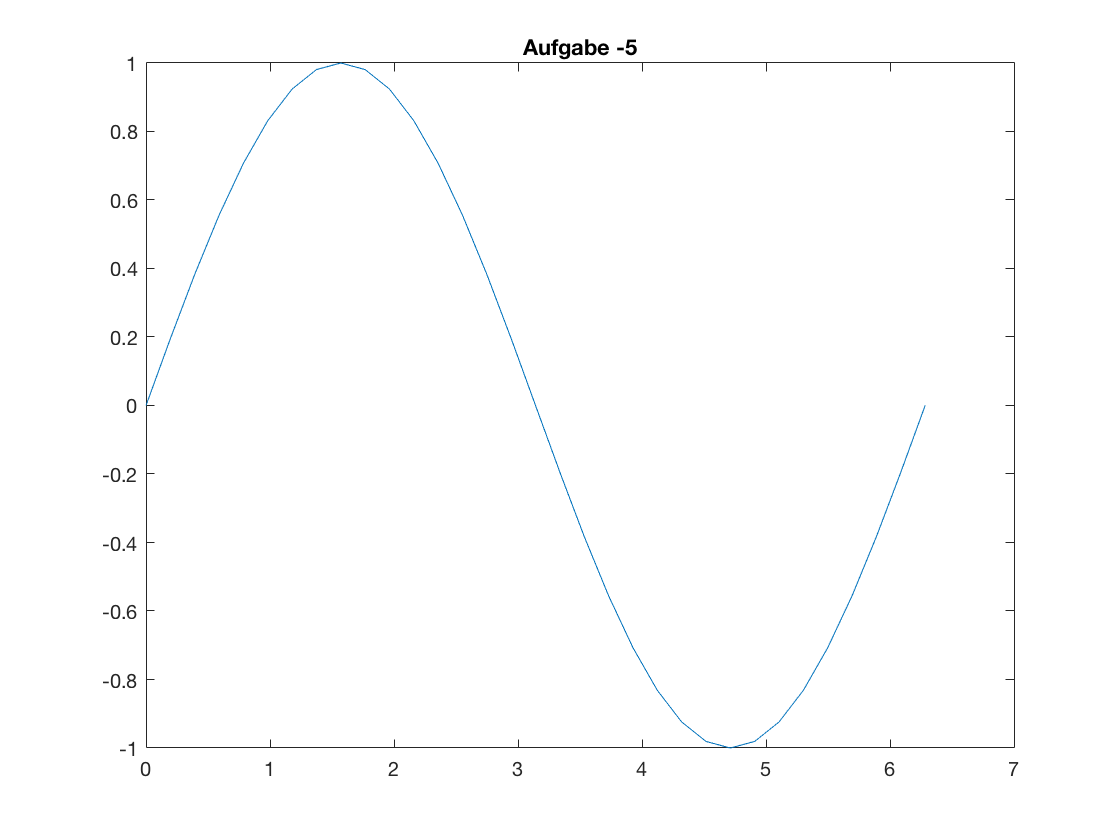

%Aufgabe -5
x=0:pi/16:2*pi; y=sin(x);
plot(x,y);
title('Aufgabe -5');

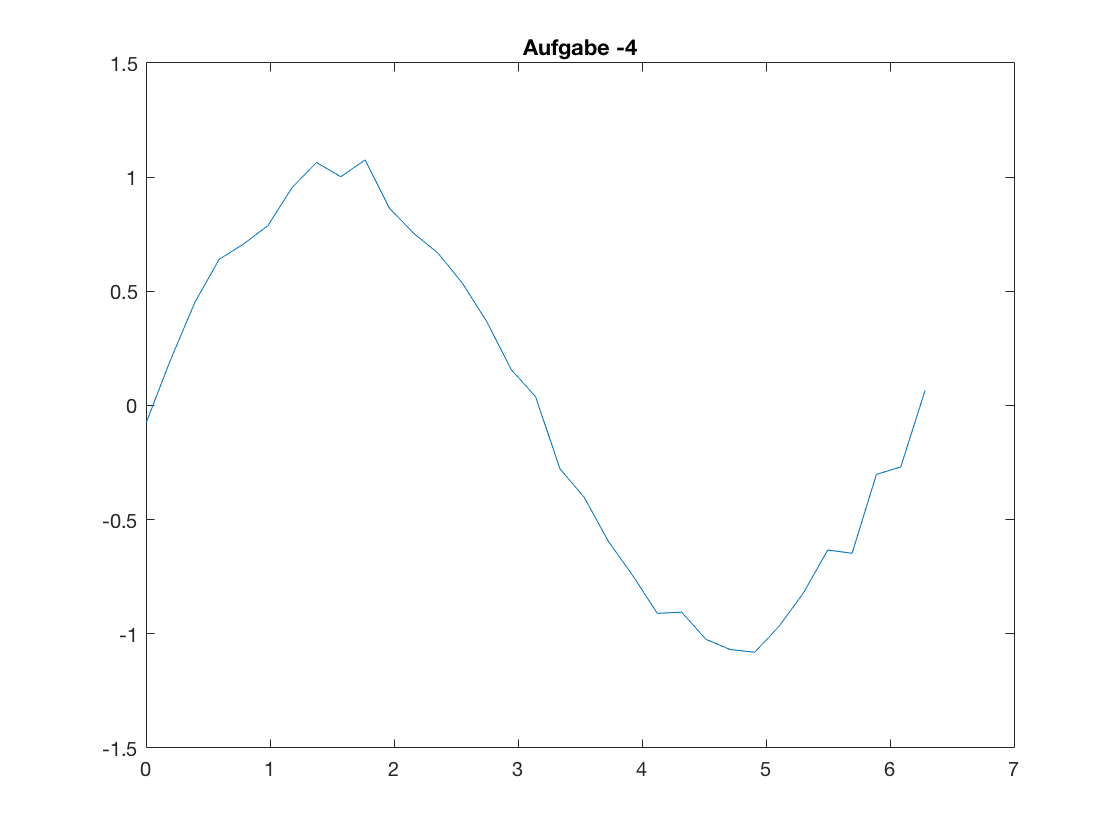


%Aufgabe -4 + Plot
rauschen=rand(size(y));
signal=y+0.2*rauschen-0.1; 
plot(x,signal);
title('Aufgabe -4');

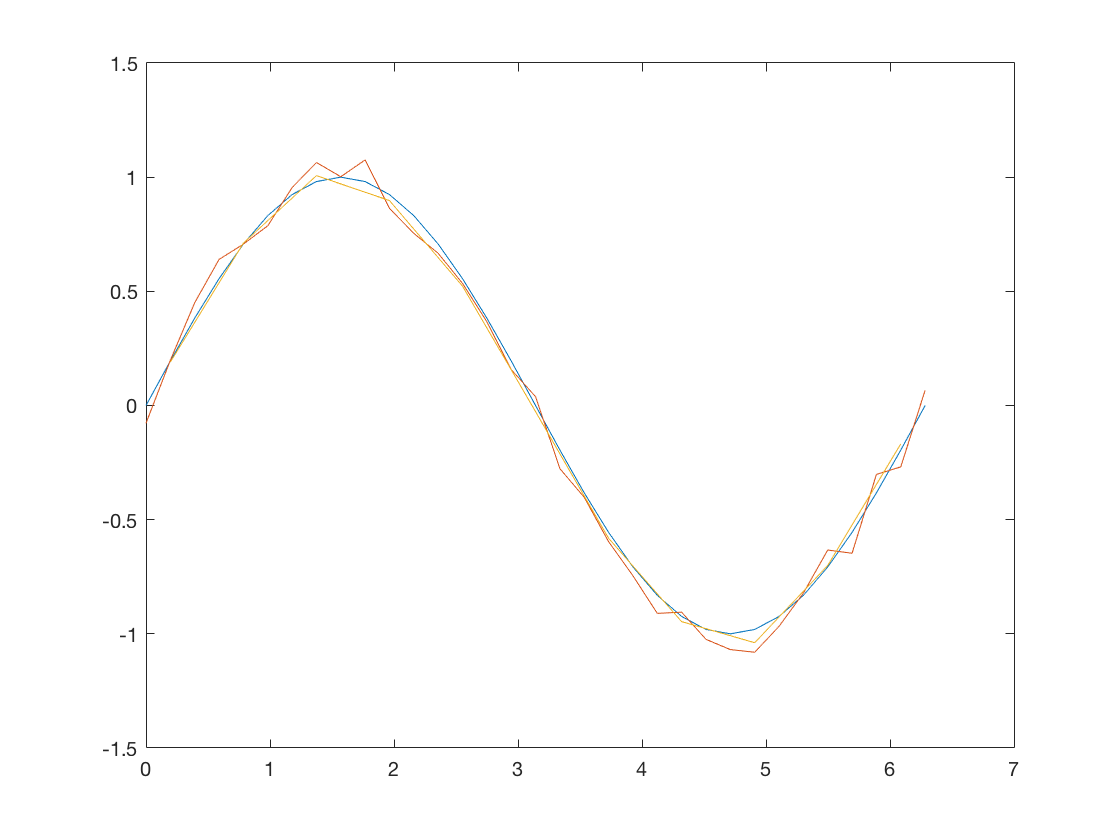


%Aufgabe -3
smooth_signal = moving_average(signal);

%Aufgabe -2
plot(x,y) 
hold on 
plot(x,signal)
plot(moving_average(x),smooth_signal);
hold off


%Aufgabe -1
meinsinus = [x;y;signal;smooth_signal zeros(1,length(x)-length(smooth_signal))]

meinsinus =          0    0.1963    0.3927    0.5890    0.7854    0.9817    1.1781    1.3744    1.5708    1.7671    1.9635    2.1598    2.3562    2.5525    2.7489    2.9452    3.1416    3.3379    3.5343    3.7306    3.9270    4.1233    4.3197    4.5160    4.7124    4.9087    5.1051    5.3014    5.4978    5.6941    5.8905    6.0868    6.2832
         0    0.1951    0.3827    0.5556    0.7071    0.8315    0.9239    0.9808    1.0000    0.9808    0.9239    0.8315    0.7071    0.5556    0.3827    0.1951    0.0000   -0.1951   -0.3827   -0.5556   -0.7071   -0.8315   -0.9239   -0.9808   -1.0000   -0.9808   -0.9239   -0.8315   -0.7071   -0.5556   -0.3827   -0.1951   -0.0000
   -0.0775    0.1982    0.4503    0.6397    0.7068    0.7870    0.9544    1.0642    1.0020    1.0756    0.8633    0.7537    0.6666    0.5349    0.3668    0.1574    0.0388   -0.2767   -0.4023   -0.5965   -0.7458   -0.9104   -0.9051   -1.0242   -1.0690   -1.0807   -0.9672   -0.8213   -0.6329   -0.6471   -0.3017   -0.2689    0.

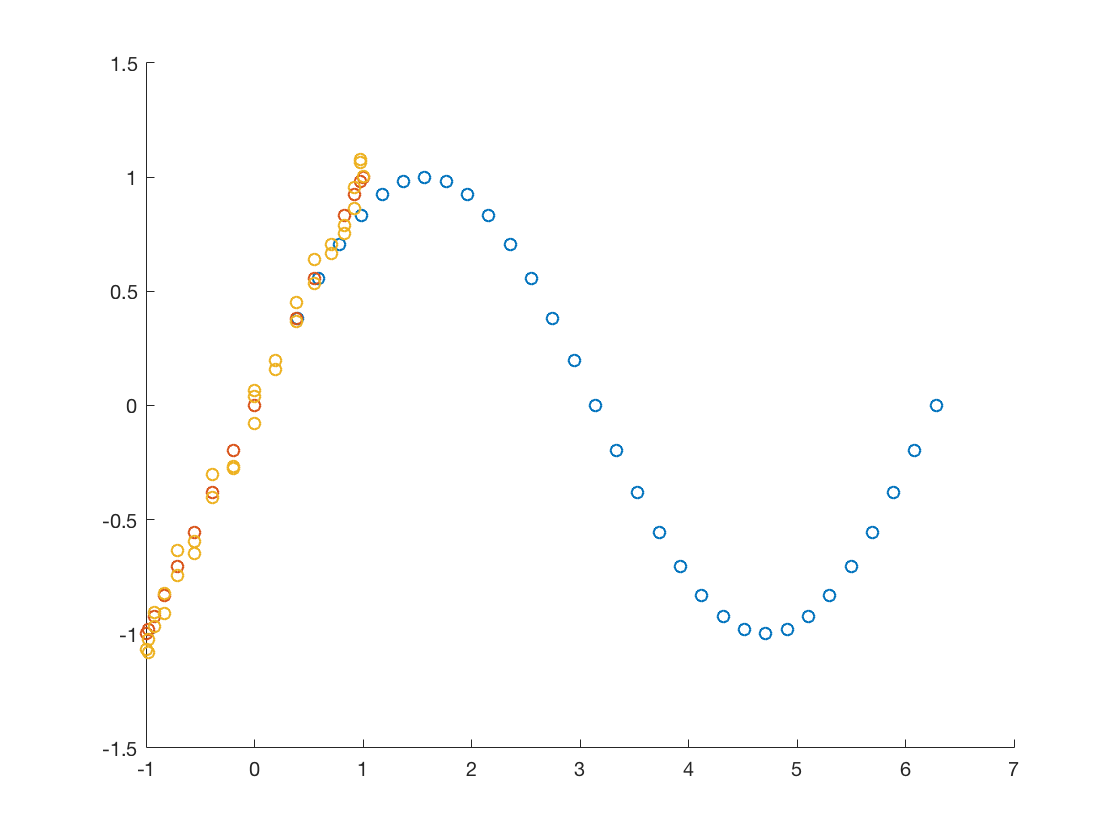

save('meinsinus.txt', 'meinsinus', '-ascii')

%Aufgabe 0
scatter(meinsinus(1,:),meinsinus(2,:))
hold on
scatter(meinsinus(2,:),meinsinus(2,:))
scatter(meinsinus(2,:),meinsinus(3,:))
hold off

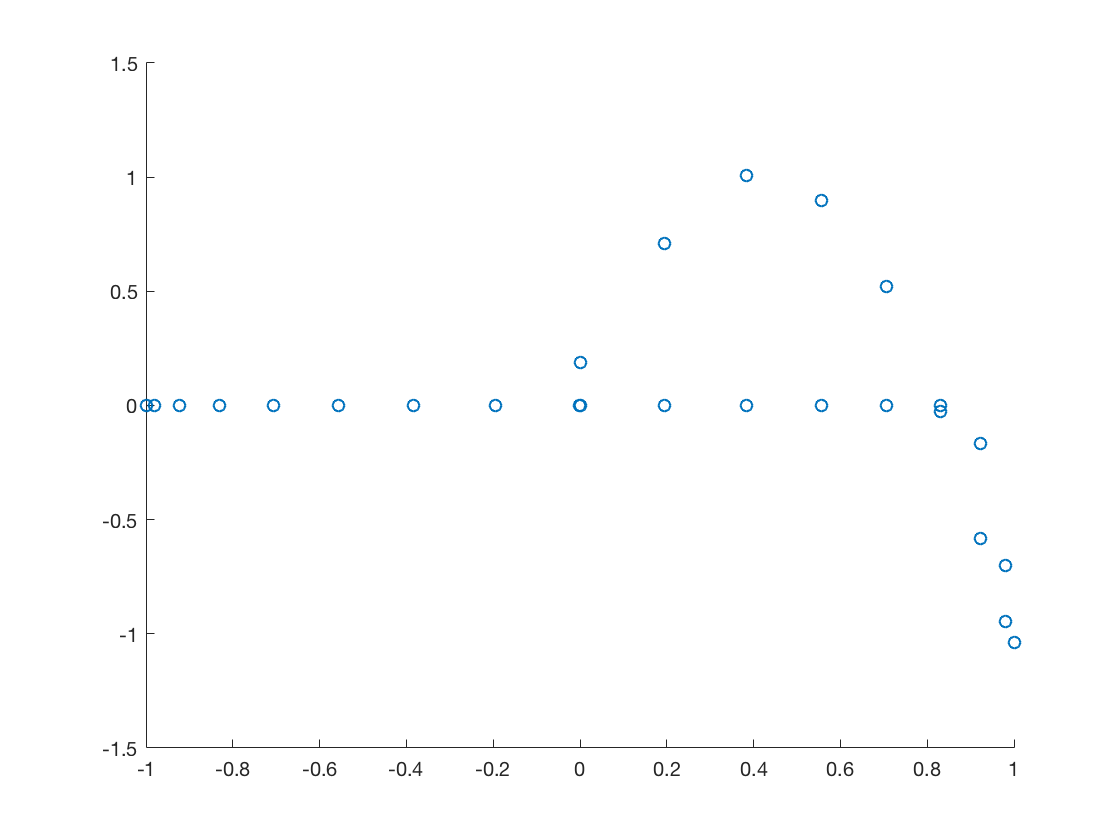

scatter(meinsinus(2,:),meinsinus(4,:))